# Frequency Domain Filtering - Overlap-Add method

Implement the Frequency Domain Filtering between $x[n]$ and $h[n]$ using the Overlap-Add method.

**Parameters** 

- 
$$x[n] = cos(2 \pi F_{0} nT_s) + cos(2 \pi F_1 n T_s)$$


- F_0 = 31.25 [Hz]

- F_1 = 312.5 [Hz]

- F_s = 1 [kHz];

- N=256; M = 129;

- h = fir1(M-1,0.25);

## Clear

clc;            % Clear the text from the Command Window
clear;          % Remove all variables from the current workspace
close all;      % Close all figures

## Parameters

Fc0 = 31.25;
Fc1 = 312.5;
Fs = 1000;
Ts = 1/Fs;

N = 256;    % FFT Points
M = 129;    % Length of the filter
h = fir1(M-1,0.25).';


## Exercise

len = 1e4;
n = 0:len-1;
x = cos(2*pi*Fc0*n*Ts).' + cos(2*pi*Fc1*n*Ts).';

% Linear Convolution used as reference
y_L = conv(x,h);

## Frequency transform and zero padding

Filtering is done using a N-FFT, and to use it, the signal must be used to create many N-length vectors. These vectors are composed of the signal samples and a zero-filled vector. In this example, N=64 and a FFT input vector is composed of N/2 samples of the signal and N/2 zeros.

% Buffer del segnale di lunghezza N_fft/2
x_b = buffer(x,N/2);

% Buffer di zeri
zero_b = zeros(size(x_b));

% Buffer del segnale
x_b = [x_b; zero_b];

% Trasformata del segnale
X_b_f = fft(x_b,N);

% Buffer del filtro di lunghezza N_fft/2
h_b = [h.', zeros(1,N/2)];

% Trasformata del filtro
H_f = fft(h_b,N);


## Product in the frequecy domain and IFFT

% Product
Y_f = zeros(size(X_b_f));
for i=1:size(Y_f,2)
    Y_f(:,i) = X_b_f(:,i).*(H_f.');
end

% IDFT
y_b = ifft(Y_f,N);


## Post IFFT processing

Since N/2 zeros have been added, the IFFT output sequences must be added between them as shown in the following figure: (https://upload.wikimedia.org/wikipedia/commons/7/77/Depiction_of_overlap-add_algorithm.png)

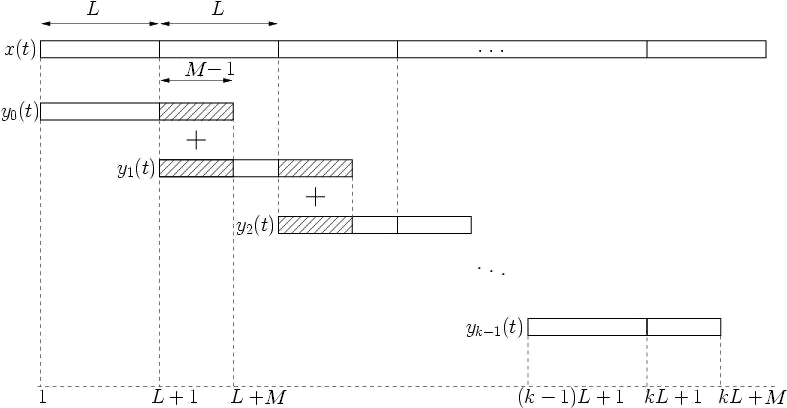

y = zeros(size(y_b,1)*size(y_b,2),1);
for i = 1:size(y_b,2)
    n_temp_1 = 1 + (i-1)*(N/2) : i*N/2;
    n_temp_2 = 1 + i*N/2 : (i+1)*N/2;
    y(n_temp_1) = y(n_temp_1) + y_b(1:N/2,i);
    y(n_temp_2) = y(n_temp_2) + y_b(1+N/2:end,i);
end


## Plot

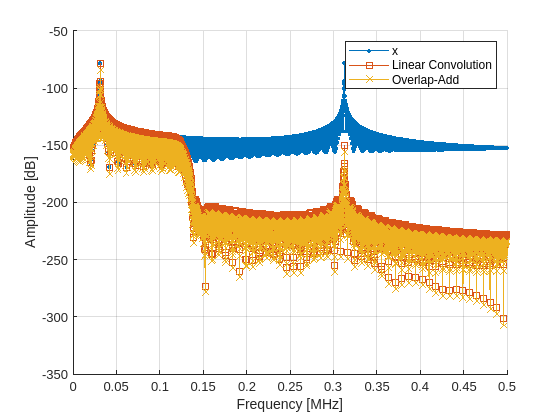

% Using 'freqz'
nFFT = 2^12; % Number of points of the fft
Xf      = freqz(x, length(x), nFFT);
Yf_L    = freqz(y_L, length(y_L), nFFT);
[Yf, w] = freqz(y, length(y), nFFT);

% Frequency normalization
w = w/pi * (Fs/2)/1e3;

% Mag to dB
Xf     = mag2db(abs(Xf)/nFFT);
Yf_L   = mag2db(abs(Yf_L)/nFFT);
Yf     = mag2db(abs(Yf)/nFFT);

% Frequency Response
figure
hold on
plot(w, Xf,   '.-')
plot(w, Yf_L, 's-')
plot(w, Yf,   'x-')
hold off
grid on
legend({'x','Linear Convolution', 'Overlap-Add'})
xlabel('Frequency [MHz]')
ylabel('Amplitude [dB]')

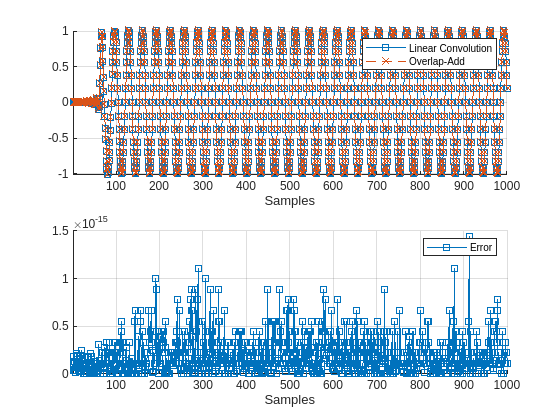


% Error between the Linear convolution and the frequency filtering
len_err = min([length(y_L),length(y)]);
error = y_L(1:len_err)-y(1:len_err);
error = abs(error);

figure;
subplot(2,1,1)
  hold on
  plot(y_L,'s-')
  plot(y,'x--')
  hold off
  xlim([1,1e3])
  legend({'Linear Convolution', 'Overlap-Add'})
  grid on
  xlabel('Samples')
subplot(2,1,2)
  hold on
  plot(error,'s-')
  hold off
  xlim([1,1e3])
  legend({'Error'})
  grid on
  xlabel('Samples')